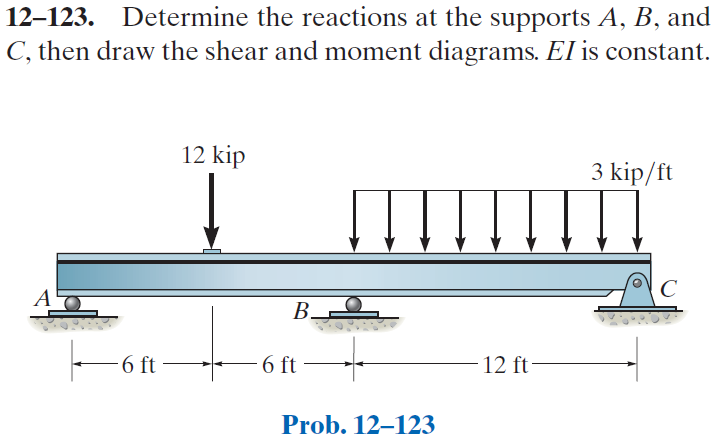

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-123P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-123P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('concentrated', 'force', -12*u.kip, 6*u.ft);
b = b.add('reaction', 'force', 'Rb', 12*u.ft);
b = b.add('reaction', 'force', 'Rc', 24*u.ft);
b = b.add('distributed', 'force', -3*u.kip/u.ft, [12 24]*u.ft);
b.L = 24*u.ft;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(432\,{\mathrm{ft}}^{2}-7\,x^{2}\right)}{16\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{\left(x-12\,\mathrm{ft}\right)\,\left(25\,x^{2}-276\,x\,\mathrm{ft}+576\,{\mathrm{ft}}^{2}\right)}{16\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\in \left(6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ -\frac{\left(x-12\,\mathrm{ft}\right)\,\left(x-24\,\mathrm{ft}\right)\,\left(2\,x^{2}-81\,x\,\mathrm{ft}+612\,{\mathrm{ft}}^{2}\right)}{16\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{3\,\left(144\,{\mathrm{ft}}^{2}-7\,x^{2}\right)}{16\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{3\,\left(25\,x^{2}-384\,x\,\mathrm{ft}+1296\,{\mathrm{ft}}^{2}\right)}{16\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\in \left(6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ -\frac{8\,x^{3}-459\,x^{2}\,\mathrm{ft}+8208\,x\,{\mathrm{ft}}^{2}-45360\,{\mathrm{ft}}^{3}}{16\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{21\,x}{8}\,\mathrm{kip} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{3\,\left(25\,x-192\,\mathrm{ft}\right)}{8}\,\mathrm{kip} & \text{ if }x\in \left(6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ -\frac{3\,\left(x-24\,\mathrm{ft}\right)\,\left(4\,x-57\,\mathrm{ft}\right)}{8}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{21}{8}\,\mathrm{kip} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{75}{8}\,\mathrm{kip} & \text{ if }x\in \left(6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ -\frac{3\,\left(8\,x-153\,\mathrm{ft}\right)}{8}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<12\,\mathrm{ft}\\ -3\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }12\,\mathrm{ft}\leq x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 2.625\,\mathrm{kip}\\ \mathrm{Rb} & 30.75\,\mathrm{kip}\\ \mathrm{Rc} & 14.625\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

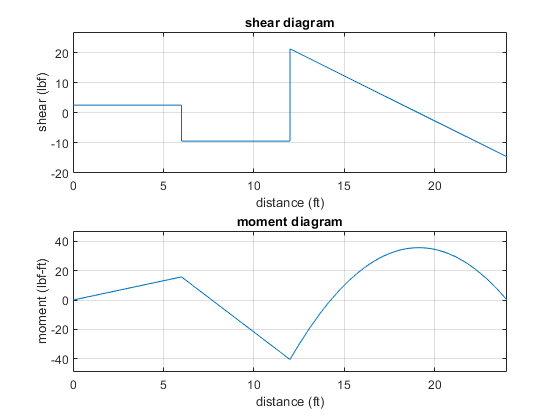

beam.shear_moment(m, v, [0 b.L], {'lbf' 'ft'});
subplot(2,1,1);
axis([0 24 -20 27]);
subplot(2,1,2);
axis([0 24 -49 47]);

# clean up

addvar(y);
setassum(old_assum, 'clear');
clear old_assum;
clear ra_vpa;